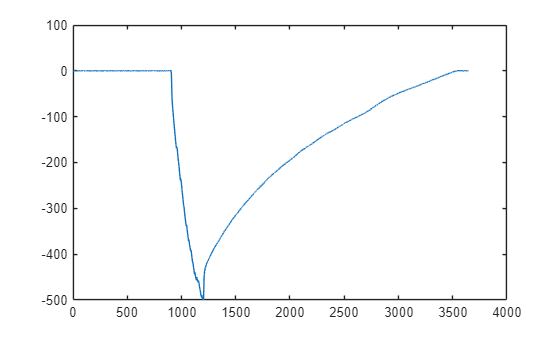

dane = load("Pomiary\dane_silniki\gyro_silnik_1sb_1400.mat");

plot(dane.out.gyro(:, 1))


%% Dane
J = 6.28e-3;       % moment bezwładności [kg*m^2]

t = dane.out.tout;               % czas [s]
omega = - double(deg2rad(dane.out.gyro(:, 1)));  % prędkość [rad/s]

%% Wybór fragmentu swobodnego wybiegu

% Przykładowe ograniczenia
t_start = 12.2;            % pominięcie stanu przejściowego [s]
omega_min = 0.1;          % pominięcie obszaru blisko zatrzymania [rad/s]

% Czas powinien być liczony od chwili wyłączenia napędu
i_start = find(t >= t_start, 1, "first");

i_stop = find(abs(omega(i_start:end)) < omega_min, 1, "first");
idx = i_start:i_start+i_stop;

t_fit = t(idx);
t_fit_shif = t_fit - t_fit(1);
omega_fit = omega(idx);

%% Lekkie wygładzenie prędkości
for i = 11:10:101
    
    omega_filtered = smoothdata(omega_fit, "sgolay", i, "Degree", 2);
    MAE = mean(abs(omega_fit - omega_filtered))
    RMSE = sqrt(mean((omega_fit - omega_filtered).^2))
    
    NRMSE = RMSE / (max(omega_fit) ...
        - min(omega_fit)) * 100
end

MAE = 6.9352e-04

RMSE = 8.8772e-04

NRMSE = 0.0120

MAE = 7.7887e-04

RMSE = 9.9530e-04

NRMSE = 0.0135

MAE = 8.3800e-04

RMSE = 0.0011

NRMSE = 0.0148

MAE = 8.5264e-04

RMSE = 0.0011

NRMSE = 0.0155

MAE = 8.6190e-04

RMSE = 0.0012

NRMSE = 0.0163

MAE = 8.8836e-04

RMSE = 0.0013

NRMSE = 0.0176

MAE = 9.2405e-04

RMSE = 0.0014

NRMSE = 0.0188

MAE = 9.5710e-04

RMSE = 0.0015

NRMSE = 0.0200

MAE = 9.9637e-04

RMSE = 0.0016

NRMSE = 0.0211

MAE = 0.0011

RMSE = 0.0017

NRMSE = 0.0224

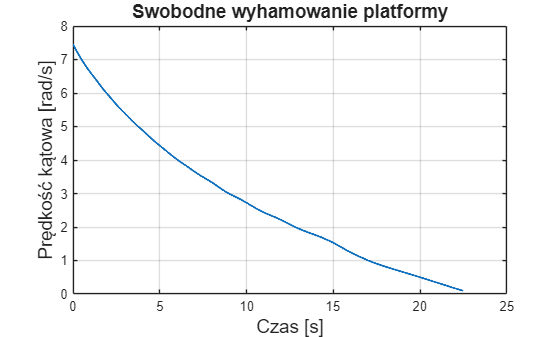



windowLength = 101;
omega_filtered = smoothdata(omega_fit, "sgolay", windowLength, "Degree", 2);

% plot(t_fit_shif, abs(omega_fit))
% hold on
plot(t_fit_shif, abs(omega_filtered), LineWidth=1.5)
title("Swobodne wyhamowanie platformy", 'Fontsize', 14)
ylabel("Prędkość kątowa [rad/s]", 'Fontsize', 14)
xlabel("Czas [s]", 'Fontsize', 14)
grid on

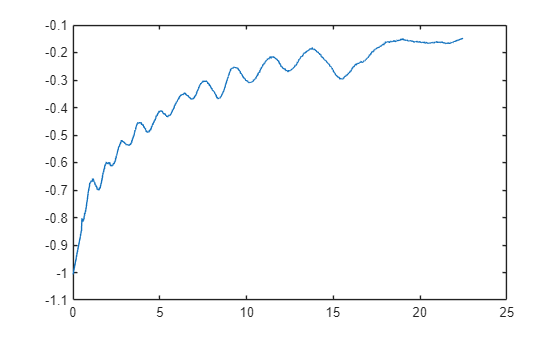

% hold off


%% Przyspieszenie kątowe

alpha = gradient(omega_filtered, t_fit_shif);
plot(t_fit_shif, alpha);


%% Dane do dopasowania

omega_abs = abs(omega_filtered);   % [rad/s]
M_op = J .* alpha .* - sign(omega_filtered);           % [N*m]

%% Pominięcie brzegów filtru i małych prędkości
edge = floor(windowLength/2);

valid = true(size(omega_filtered));

valid(1:edge) = false;
valid(end-edge+1:end) = false;

% omega_data = omega_abs(valid);
M_data = M_op(valid);
omega_data = omega_abs(valid);

%% Dopasowanie:
% M_op = M_C + b*omega + c*omega^2

p = polyfit(omega_data, M_data, 2);

c   = p(1);
b   = p(2);
M_C = p(3);

%% Obliczenie modelu

M_model = polyval(p, omega_data);

%% Ocena dopasowania


MAE = mean(abs(M_data - M_model))

MAE = 1.4795e-04

RMSE = sqrt(mean((M_data - M_model).^2))

RMSE = 1.8364e-04


NRMSE = RMSE / (max(M_data) - min(M_data)) * 100

NRMSE = 4.3139


SS_res = sum((M_data - M_model).^2);
SS_tot = sum((M_data - mean(M_data)).^2);

R2 = 1 - SS_res / SS_tot;

%% Wyniki

fprintf("M_C = %.6e N*m\n", M_C);

M_C = 1.059143e-03 N*m


fprintf("M_C = %.3f mN*m\n", M_C * 1000);

M_C = 1.059 mN*m



fprintf("b   = %.6e N*m*s/rad\n", b);

b   = 8.693789e-05 N*m*s/rad


fprintf("c   = %.6e N*m*s^2/rad^2\n", c);

c   = 6.430295e-05 N*m*s^2/rad^2



fprintf("R^2 = %.4f\n", R2);

R^2 = 0.9640


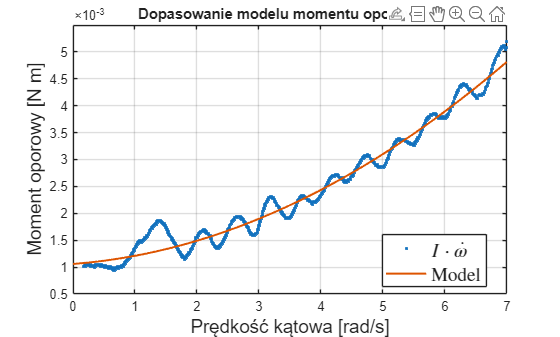


%% Wykres

omega_plot = linspace(0, max(omega_data), 300);

M_plot = M_C ...
       + b .* omega_plot ...
       + c .* omega_plot.^2;

figure;

plot(omega_data, M_data, ".", ...
    "DisplayName", "$$I\cdot\dot{\omega}$$");

hold on;

plot(omega_plot, M_plot, ...
    "LineWidth", 1.5, ...
    "DisplayName", "Model");

grid on;
xlabel("Prędkość kątowa [rad/s]", 'Fontsize', 14);
ylabel("Moment oporowy [N m]", 'Fontsize', 14);
legend("Location", "best", 'Interpreter', 'latex', 'FontSize', 14);

title("Dopasowanie modelu momentu oporowego");
hold off

disp("section end")

section end


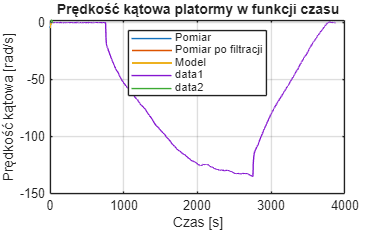

% SEKLCJA POWTARZAJĄCEGO SIĘ KODU DO DANYCH DO TABELI

dane_do_tabeli = load("Pomiary\dane_silniki\gyro_silnik_1sb_1100.mat");

plot(dane_do_tabeli.out.gyro(:, 1))

t = dane_do_tabeli.out.tout;               % czas [s]
omega = double(deg2rad(dane_do_tabeli.out.gyro(:, 1)));  % prędkość [rad/s]

plot(t, abs(omega))
ylabel("Prędkość kątowa [rad/s]")
xlabel("Czas [s]")
title("Prędkość kątowa platormy w funkcji czasu")
grid on

%% Wybór fragmentu swobodnego wybiegu

% Ograniczenia
t_start = 27.90;            % moment rozpoczęcia hamowania [s]
omega_min = 0.1;          % pominięcie obszaru blisko zatrzymania [rad/s]

% Czas powinien być liczony od chwili wyłączenia napędu
idx = t >= t_start & abs(omega) >= omega_min;

t_fit = t(idx);
t_fit_shif = t_fit - t_fit(1);
omega_fit = omega(idx);

%% Lekkie wygładzenie prędkości

omega_filtered = smoothdata(omega_fit, "sgolay", 101);

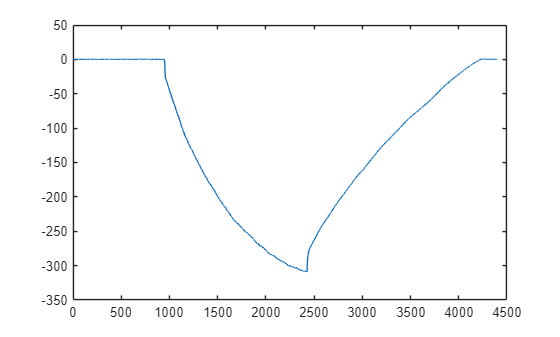

dane_do_tabeli = load("Pomiary\dane_silniki\gyro_silnik_1sb_1150.mat");

plot(dane_do_tabeli.out.gyro(:, 1))

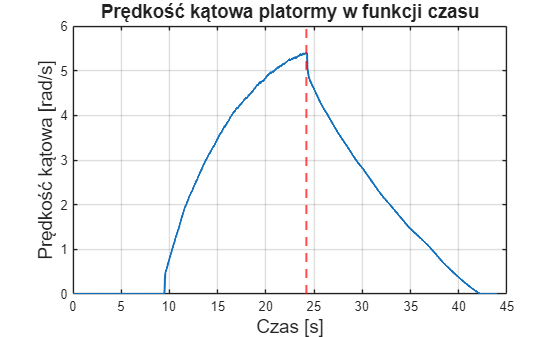


t = dane_do_tabeli.out.tout;               % czas [s]
omega = double(deg2rad(dane_do_tabeli.out.gyro(:, 1)));  % prędkość [rad/s]

plot(t, abs(omega), LineWidth=1.5)
ylabel("Prędkość kątowa [rad/s]", 'Fontsize', 14)
xlabel("Czas [s]", 'Fontsize', 14)
title("Prędkość kątowa platormy w funkcji czasu", 'Fontsize', 14)
xline(24.2, 'r--', LineWidth=1.5);
grid on

%% Wybór fragmentu swobodnego wybiegu

% Ograniczenia
t_start = 24.60;            % moment rozpoczęcia hamowania [s]
omega_min = 0.1;          % pominięcie obszaru blisko zatrzymania [rad/s]

% Czas powinien być liczony od chwili wyłączenia napędu
idx = t >= t_start & abs(omega) >= omega_min;

t_fit = t(idx);
t_fit_shif = t_fit - t_fit(1);
omega_fit = omega(idx);

%% Lekkie wygładzenie prędkości

omega_filtered = smoothdata(omega_fit, "sgolay", 101);

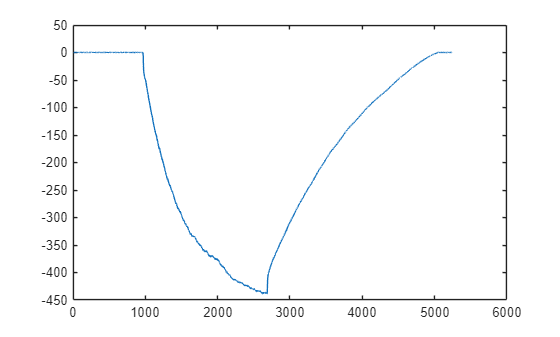

dane_do_tabeli = load("Pomiary\dane_silniki\gyro_silnik_1sb_1200.mat");

plot(dane_do_tabeli.out.gyro(:, 1))

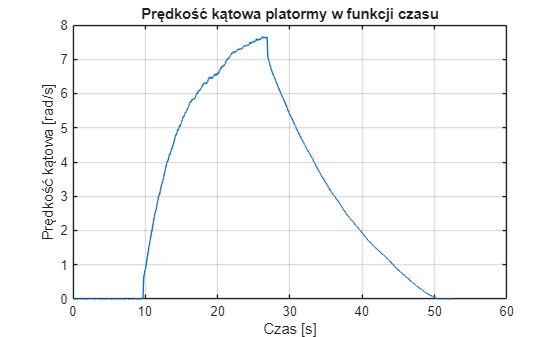


t = dane_do_tabeli.out.tout;               % czas [s]
omega = double(deg2rad(dane_do_tabeli.out.gyro(:, 1)));  % prędkość [rad/s]

plot(t, abs(omega))
ylabel("Prędkość kątowa [rad/s]")
xlabel("Czas [s]")
title("Prędkość kątowa platormy w funkcji czasu")
grid on

%% Wybór fragmentu swobodnego wybiegu

% Ograniczenia
t_start = 27.20;            % moment rozpoczęcia hamowania [s]
omega_min = 0.1;          % pominięcie obszaru blisko zatrzymania [rad/s]

% Czas powinien być liczony od chwili wyłączenia napędu
idx = t >= t_start & abs(omega) >= omega_min;

t_fit = t(idx);
t_fit_shif = t_fit - t_fit(1);
omega_fit = omega(idx);

%% Lekkie wygładzenie prędkości

omega_filtered = smoothdata(omega_fit, "sgolay", 101);

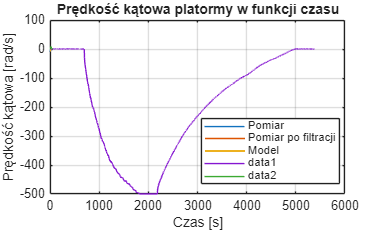

dane_do_tabeli = load("Pomiary\dane_silniki\gyro_silnik_1sb_1250.mat");

plot(dane_do_tabeli.out.gyro(:, 1))

t = dane_do_tabeli.out.tout;               % czas [s]
omega = double(deg2rad(dane_do_tabeli.out.gyro(:, 1)));  % prędkość [rad/s]

plot(t, abs(omega))
ylabel("Prędkość kątowa [rad/s]")
xlabel("Czas [s]")
title("Prędkość kątowa platormy w funkcji czasu")
grid on

%% Wybór fragmentu swobodnego wybiegu

% Ograniczenia
t_start = 22;            % moment rozpoczęcia hamowania [s]
omega_min = 0.1;          % pominięcie obszaru blisko zatrzymania [rad/s]

% Czas powinien być liczony od chwili wyłączenia napędu
idx = t >= t_start & abs(omega) >= omega_min;

t_fit = t(idx);
t_fit_shif = t_fit - t_fit(1);
omega_fit = omega(idx);

%% Lekkie wygładzenie prędkości

omega_filtered = smoothdata(omega_fit, "sgolay", 101);

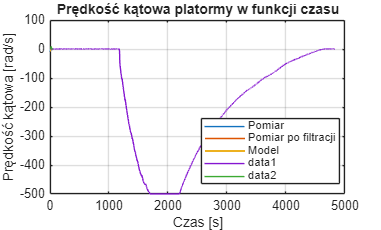

dane_do_tabeli = load("Pomiary\dane_silniki\gyro_silnik_1sb_1300.mat");

plot(dane_do_tabeli.out.gyro(:, 1))

t = dane_do_tabeli.out.tout;               % czas [s]
omega = double(deg2rad(dane_do_tabeli.out.gyro(:, 1)));  % prędkość [rad/s]

plot(t, abs(omega))
ylabel("Prędkość kątowa [rad/s]")
xlabel("Czas [s]")
title("Prędkość kątowa platormy w funkcji czasu")
grid on

%% Wybór fragmentu swobodnego wybiegu

% Ograniczenia
t_start = 22.30;            % moment rozpoczęcia hamowania [s]
omega_min = 0.1;          % pominięcie obszaru blisko zatrzymania [rad/s]

% Czas powinien być liczony od chwili wyłączenia napędu
idx = t >= t_start & abs(omega) >= omega_min;

t_fit = t(idx);
t_fit_shif = t_fit - t_fit(1);
omega_fit = omega(idx);

%% Lekkie wygładzenie prędkości

omega_filtered = smoothdata(omega_fit, "sgolay", 101);

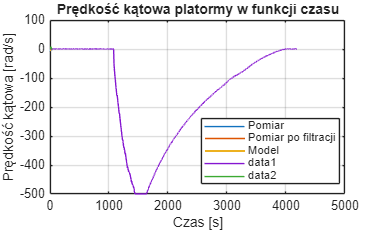

dane_do_tabeli = load("Pomiary\dane_silniki\gyro_silnik_1sb_1350.mat");

plot(dane_do_tabeli.out.gyro(:, 1))

t = dane_do_tabeli.out.tout;               % czas [s]
omega = double(deg2rad(dane_do_tabeli.out.gyro(:, 1)));  % prędkość [rad/s]

plot(t, abs(omega))
ylabel("Prędkość kątowa [rad/s]")
xlabel("Czas [s]")
title("Prędkość kątowa platormy w funkcji czasu")
grid on

%% Wybór fragmentu swobodnego wybiegu

% Ograniczenia
t_start = 16.50;            % moment rozpoczęcia hamowania [s]
omega_min = 0.1;          % pominięcie obszaru blisko zatrzymania [rad/s]

% Czas powinien być liczony od chwili wyłączenia napędu
idx = t >= t_start & abs(omega) >= omega_min;

t_fit = t(idx);
t_fit_shif = t_fit - t_fit(1);
omega_fit = omega(idx);

%% Lekkie wygładzenie prędkości

omega_filtered = smoothdata(omega_fit, "sgolay", 101);

dane_do_tabeli = load("Pomiary\dane_silniki\gyro_silnik_1sb_1400.mat");

plot(dane_do_tabeli.out.gyro(:, 1))

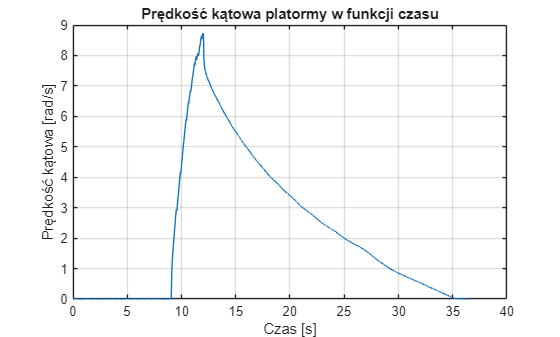


t = dane_do_tabeli.out.tout;               % czas [s]
omega = double(deg2rad(dane_do_tabeli.out.gyro(:, 1)));  % prędkość [rad/s]

plot(t, abs(omega))
ylabel("Prędkość kątowa [rad/s]")
xlabel("Czas [s]")
title("Prędkość kątowa platormy w funkcji czasu")
grid on

%% Wybór fragmentu swobodnego wybiegu

% Ograniczenia
t_start = 12.35;            % moment rozpoczęcia hamowania [s]
omega_min = 0.1;          % pominięcie obszaru blisko zatrzymania [rad/s]

% Czas powinien być liczony od chwili wyłączenia napędu
idx = t >= t_start & abs(omega) >= omega_min;

t_fit = t(idx);
t_fit_shif = t_fit - t_fit(1);
omega_fit = omega(idx);

%% Lekkie wygładzenie prędkości

omega_filtered = smoothdata(omega_fit, "sgolay", 101);

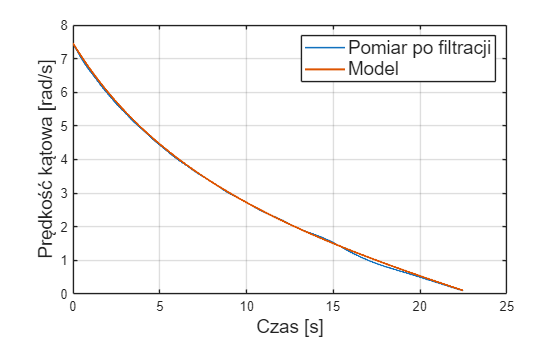

model = @(t, omega) ...
    -sign(omega) .* ...
    (M_C + b.*abs(omega) + c.*omega.^2) ./ J;

[~, omega_sim] = ode45( ...
    model, ...
    t_fit_shif, ...
    omega_filtered(1));

figure;
% plot(t_fit_shif, omega_fit, ...
%     "DisplayName", "Pomiar");



plot(t_fit_shif, abs(omega_filtered), ...
    "LineWidth", 1.2, ...
    "DisplayName", "Pomiar po filtracji");
hold on;
plot(t_fit_shif, abs(omega_sim), ...
    "LineWidth", 1.5, ...
    "DisplayName", "Model");

grid on;
xlabel("Czas [s]", 'Fontsize', 14);
ylabel("Prędkość kątowa [rad/s]", 'Fontsize', 14);
legend("Location", "best", 'FontSize', 14);
hold off

RMSE_omega = sqrt(mean( ...
    (omega_filtered - omega_sim).^2))

RMSE_omega = 0.0421


NRMSE_omega = RMSE_omega / ...
    (max(omega_filtered) - min(omega_filtered)) * 100

NRMSE_omega = 0.5727

dane_2 = load("Pomiary\dane_silniki\gyro_silnik_1sb_1400.mat");

plot(dane_2.out.gyro(:, 1))


t = dane_2.out.tout;               % czas [s]
omega = double(deg2rad(dane_2.out.gyro(:, 1)));  % prędkość [rad/s]

plot(t, abs(omega))
ylabel("Prędkość kątowa [rad/s]")
xlabel("Czas [s]")
title("Prędkość kątowa platormy w funkcji czasu")
grid on

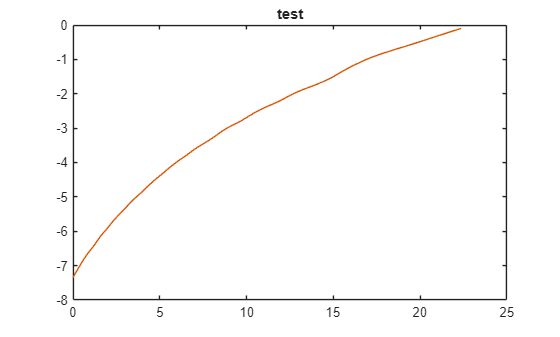

%% Wybór fragmentu swobodnego wybiegu

% Przykładowe ograniczenia
t_start = 12.30;            % pominięcie stanu przejściowego [s]
omega_min = 0.1;          % pominięcie obszaru blisko zatrzymania [rad/s]

% Czas powinien być liczony od chwili wyłączenia napędu
idx = t >= t_start & abs(omega) >= omega_min;

t_fit = t(idx);
t_fit_shif = t_fit - t_fit(1);
omega_fit = omega(idx);

%% Lekkie wygładzenie prędkości

omega_filtered = smoothdata(omega_fit, "sgolay", 31);

plot(t_fit_shif, omega_fit)
hold on
plot(t_fit_shif, omega_filtered)
title("test")
hold off

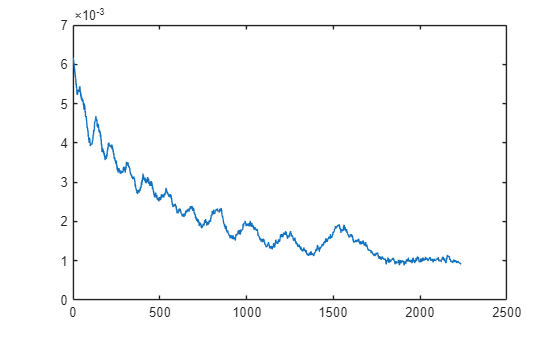


alpha = gradient(omega_filtered, t_fit_shif);
M_op = J .* abs(alpha); 
omega_abs = abs(omega_fit);

plot(M_op)

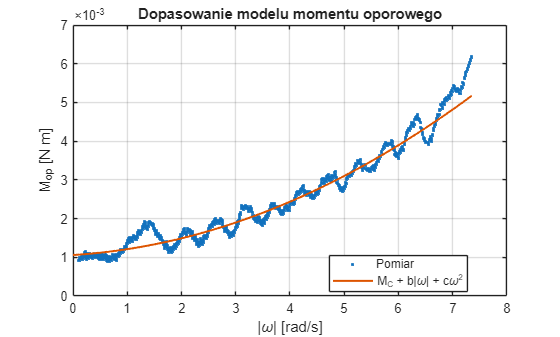



%% Wykres
omega_plot = linspace(0, max(omega_abs), 300);

M_plot = M_C ...
       + b .* omega_plot ...
       + c .* omega_plot.^2;

figure;

plot(omega_abs, M_op, ".", ...
    "DisplayName", "Pomiar");

hold on;

plot(omega_plot, M_plot, ...
    "LineWidth", 1.5, ...
    "DisplayName", "M_C + b|\omega| + c\omega^2");

grid on;
xlabel("|\omega| [rad/s]");
ylabel("M_{op} [N m]");
legend("Location", "best");

title("Dopasowanie modelu momentu oporowego");
hold off

disp("section end")

section end


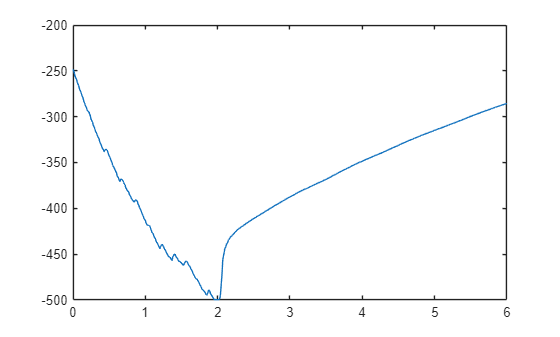

% Znane parametry
J = 6.28e-3;   % [kg*m^2]

% Parametry wyznaczone podczas swobodnego wybiegu
M_C = 1,06e-3;     % [N*m]
b   = 8,69e-5;     % [N*m*s/rad]
c   = 6,43e-5;     % [N*m*s^2/rad^2]

t_fit = t(1000:1600);
t_fit_shif = t_fit - t_fit(1);

omega_raw = dane.out.gyro(1000:1600, 1);
plot(t_fit_shif, omega_raw)

omega_filtered = smoothdata(omega_raw, "sgolay", 60);

fit = polyfit(t_fit_shif, omega_filtered, 3)

fit = 1×4 single row vector
   -7.6617   82.6501 -230.1850 -256.9264


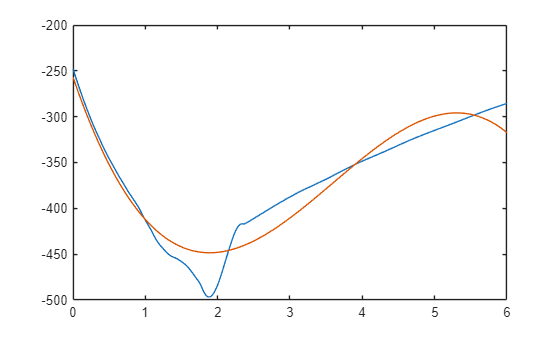

test = polyval(fit, t_fit_shif);

plot(t_fit_shif, omega_filtered)
hold on
plot(t_fit_shif, test)
hold off

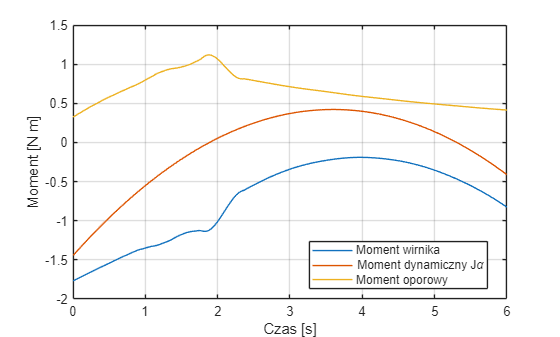


alpha = gradient(test, t_fit_shif);


% omega_filtered - prędkość stanowiska [rad/s]
% alpha          - przyspieszenie stanowiska [rad/s^2]

%% Wartość momentu oporowego

M_op_abs = M_C ...
         + b .* abs(omega_filtered) ...
         + c .* omega_filtered.^2;

%% Moment oporowy ze znakiem
% Jest zawsze przeciwny do kierunku prędkości.

M_op_signed = -sign(omega_filtered) .* M_op_abs;

%% Moment generowany przez wirnik

M_rotor = J .* alpha - M_op_signed;

% Równoważnie:
% M_rotor = J .* alpha ...
%         + sign(omega_filtered) .* M_op_abs;

%% Wykres

figure;

plot(t_fit_shif, M_rotor, ...
    "DisplayName", "Moment wirnika");

hold on;

plot(t_fit_shif, J .* alpha, ...
    "DisplayName", "Moment dynamiczny J\alpha");

plot(t_fit_shif, M_op_signed, ...
    "DisplayName", "Moment oporowy");

grid on;
xlabel("Czas [s]");
ylabel("Moment [N m]");
legend("Location", "best");
hold off

disp("section end")

section end


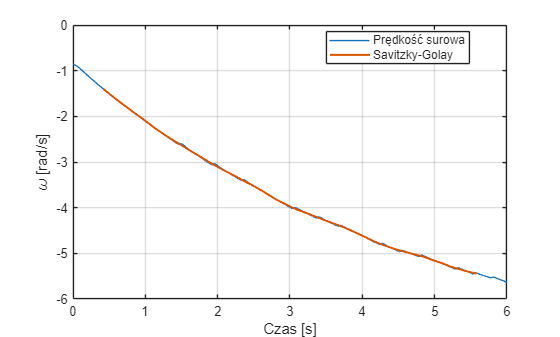

%% Dane

J = 6.28e-3;   % [kg*m^2]

t_fit = t(1000:1600);
t_fit_shift = t_fit - t_fit(1);

% Konwersja z deg/s na rad/s
omega_raw = deg2rad(double(dane.out.gyro(1000:1600, 1)));

%% Savitzky-Golay

polyOrder = 3;
windowLength = 85;    % 31 próbek przy 85 Hz = około 0.365 s

dt = median(diff(t_fit_shift));

% Wygładzona prędkość
omega_filtered = sgolayfilt(omega_raw, polyOrder, windowLength);

% Współczynniki filtru Savitzky'ego-Golaya
[~, G] = sgolay(polyOrder, windowLength);

% Bezpośrednia pierwsza pochodna prędkości
alpha = conv( ...
    omega_raw, ...
    factorial(1) / (-dt) .* G(:, 2), ...
    "same");

%% Pominięcie próbek brzegowych

edge = floor(windowLength / 2);

valid = false(size(omega_raw));
valid(edge + 1:end - edge) = true;

t_model = t_fit_shift(valid);
omega_model = omega_filtered(valid);
alpha_model = alpha(valid);

%% Parametry oporu

M_C = 8.739247e-4;   % [N*m]
b   = 3.600239e-4;   % [N*m*s/rad]
c   = 3.801205e-6;   % [N*m*s^2/rad^2]

%% Moment oporowy

M_op_abs = M_C ...
         + b .* abs(omega_model) ...
         + c .* omega_model.^2;

M_op_signed = -sign(omega_model) .* M_op_abs;

%% Moment wypadkowy i moment wirnika

M_dynamic = J .* alpha_model;

M_rotor = M_dynamic - M_op_signed;

figure;

plot(t_fit_shift, omega_raw, ...
    "DisplayName", "Prędkość surowa");

hold on;

plot(t_model, omega_model, ...
    "LineWidth", 1.5, ...
    "DisplayName", "Savitzky-Golay");

grid on;
xlabel("Czas [s]");
ylabel("\omega [rad/s]");
legend("Location", "best");
hold off;

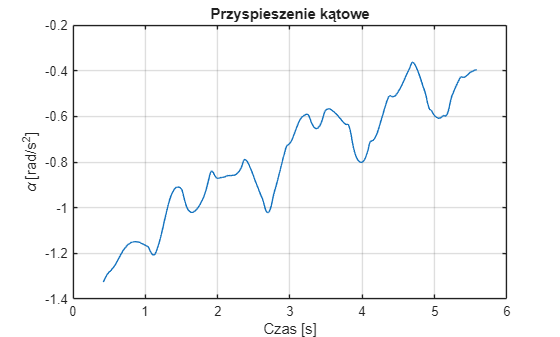


figure;

plot(t_model, alpha_model);

grid on;
xlabel("Czas [s]");
ylabel("\alpha [rad/s^2]");
title("Przyspieszenie kątowe");

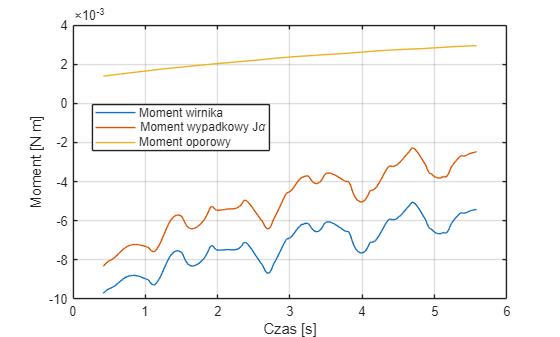


figure;

plot(t_model, M_rotor, ...
    "DisplayName", "Moment wirnika");

hold on;

plot(t_model, M_dynamic, ...
    "DisplayName", "Moment wypadkowy J\alpha");

plot(t_model, M_op_signed, ...
    "DisplayName", "Moment oporowy");

grid on;
xlabel("Czas [s]");
ylabel("Moment [N m]");
legend("Location", "best");
hold off;

disp("section end")

section end


J = 6.28e-3;   % [kg*m^2]

M_C = 8.739247e-4;
b   = 3.600239e-4;
c   = 3.801205e-6;

t = dane.out.tout;

% Pomiar źródłowy prawdopodobnie w deg/s
omega = deg2rad(double(dane.out.gyro(:, 1)));

%% Zakres analizowanego szarpnięcia

t1 = 9.67;   % początek zdarzenia [s]
t2 = 9.77;   % koniec zdarzenia [s]

idx_event = t >= t1 & t <= t2;

% Krótkie fragmenty przed i po zdarzeniu
windowBefore = t >= t1 - 0.10 & t < t1;
windowAfter  = t > t2 & t <= t2 + 0.10;

%% Prędkość przed i po zdarzeniu

% Mediana ogranicza wpływ pojedynczych zakłóceń
omega_before = median(omega(windowBefore));
omega_after  = median(omega(windowAfter));

delta_omega = omega_after - omega_before;
delta_t = t2 - t1;

%% Średni moment wypadkowy

alpha_avg = delta_omega / delta_t;

M_net_avg = J * alpha_avg;

%% Moment oporowy podczas zdarzenia

omega_event = omega(idx_event);
t_event = t(idx_event);

M_op_abs = M_C ...
         + b .* abs(omega_event) ...
         + c .* omega_event.^2;

M_op_signed = -sign(omega_event) .* M_op_abs;

%% Oszacowany moment wirnika

M_rotor_avg = M_net_avg - mean(M_op_signed);

%% Impuls momentu wirnika

angularImpulse = ...
    J * delta_omega ...
    - trapz(t_event, M_op_signed);

%% Wyniki

fprintf("Zmiana prędkości Δω:       %.6f rad/s\n", delta_omega);

Zmiana prędkości Δω:       -0.691910 rad/s


fprintf("Czas zdarzenia Δt:          %.6f s\n", delta_t);

Czas zdarzenia Δt:          0.100000 s


fprintf("Średnie przyspieszenie:     %.6f rad/s^2\n", alpha_avg);

Średnie przyspieszenie:     -6.919103 rad/s^2



fprintf("Średni moment wypadkowy:    %.6e N*m\n", M_net_avg);

Średni moment wypadkowy:    -4.345196e-02 N*m


fprintf("Średni moment wirnika:      %.6e N*m\n", M_rotor_avg);

Średni moment wirnika:      -4.443643e-02 N*m



fprintf("Impuls momentu wirnika:     %.6e N*m*s\n", ...
    angularImpulse);

Impuls momentu wirnika:     -4.443637e-03 N*m*s


disp("section end")

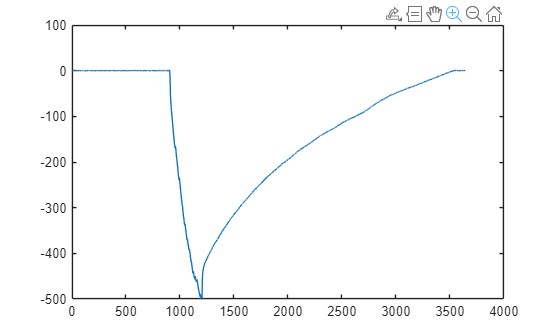

dane_test = load("Pomiary\dane_silniki\gyro_silnik_1sb_1400.mat");

plot(dane_test.out.gyro(:, 1))

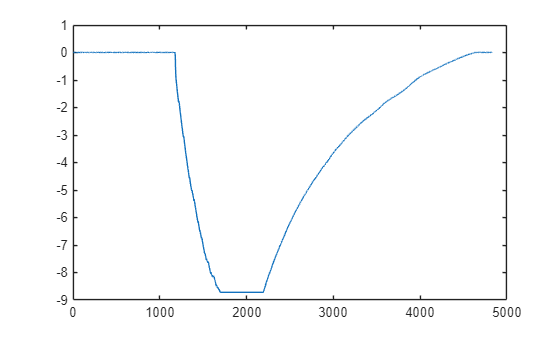

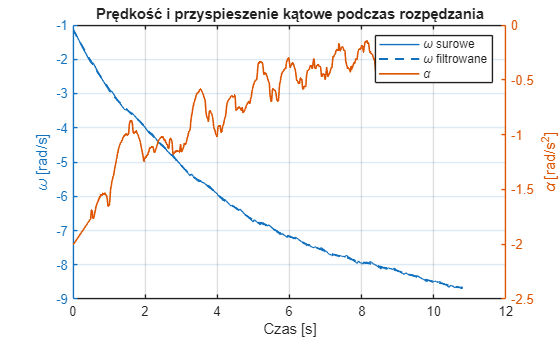

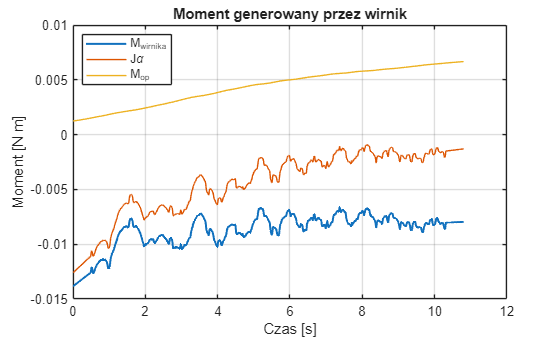

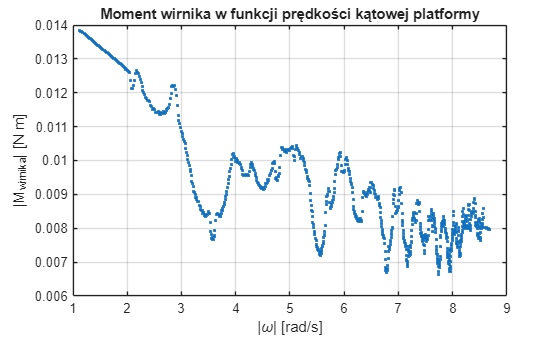

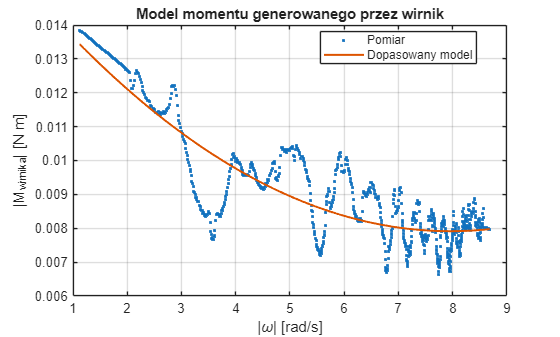

M(omega) = 1.182495e-04 * omega^2 + -1.881663e-03 * omega + 1.539866e-02
